%dimension du tableau
n=1:12; %colonnes du tableau
length(n)

ans = 12

m=1:10; %lignes du tableau
length(m)

ans = 10

%fenêtre
ligFen=10;
colFen1=8;
colFen2=7;
colFen3=6;
colFen4=5;
%radiateur
colRad=3;
ligRad=1;
valRad=40;
%t-800
ligMa1=5;
ligMa2=6;
colMa1=6;
colMa2=7;
valMa=35;
valInit =25;
piece = zeros(10,12);
% propriétés physique
rhoAir=0.0013;
c= 1.01;%chaleur spécifique
k=2.5*10^(-2);% W/m/K
fluxMur=69;
fluxFen=150;
tExt=10;
epaiMur=0.2;
gamaBeton=0.92;
epaiFen=0.05;
gamaVerre=1.13;



for ligne = m
 for colonne = n
 % si c'est le point de la fenêtre, on lui donne sa temperature
 if (ligne==ligFen && (colonne==colFen1||colonne==colFen2||colonne==colFen3||colonne==colFen4))
 piece(ligne,colonne)= tExt+fluxFen*epaiFen/(gamaVerre) ;

% 1
 % sinon si c'est le point de le radiateur, on lui donne sa temperature
 elseif (ligne==ligRad && colonne==colRad)
 piece(ligne,colonne)=valRad;

 % sinon si c'est le point de la machine, on lui donne sa temperature
 elseif ((ligne==ligMa1 || ligne==ligMa2 ) &&( colonne==colMa1 || colonne==colMa2))
 piece(ligne,colonne)=valMa;

 % cas de la conduction dans les murs
 elseif (ligne==1 || colonne==1 || ligne==10 || colonne== 12)
 piece(ligne,colonne)= tExt+fluxMur*epaiMur/(gamaBeton) ;
 end
 end
end
 disp(piece);

   25.0000   25.0000   40.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000
   25.0000         0         0         0         0         0         0         0         0         0         0   25.0000
   25.0000         0         0         0         0         0         0         0         0         0         0   25.0000
   25.0000         0         0         0         0         0         0         0         0         0         0   25.0000
   25.0000         0         0         0         0   35.0000   35.0000         0         0         0         0   25.0000
   25.0000         0         0         0         0   35.0000   35.0000         0         0         0         0   25.0000
   25.0000         0         0         0         0         0         0         0         0         0         0   25.0000
   25.0000         0         0         0         0         0         0         0         0         0         0   25.0000
   25.0000         0         0  

 
 A=zeros(80,80);
for i=1:80
 if (i==1)
 A(i,i)=-4;
 A(i,i+10)=1;
 A(i,i+1)=1;

 elseif (i==80)
 A(i,i)=-4;
 A(i,i-10)=1;
 A(i,i-1)=1;

 elseif(i==10)
 A(i,i)=-4;
 A(i,i+10)=1;
 A(i,i-1)=1;
 elseif(i==71)
 A(i,i)=-4;
 A(i,i-10)=1;
 A(i,i+1)=1;
 % t800

 elseif(i==35 || i==36 ||i==45 || i==46 )
 A(i,i)=1;

 elseif(i==25||i==26)
 A(i,i)=-4;
 A(i,i-10)=1;
 A(i,i-1)=1;
 A(i,i+1)=1;

 elseif(i==55||i==56)
 A(i,i)=-4;
 A(i,i+10)=1;
 A(i,i-1)=1;
 A(i,i+1)=1;

 elseif(i==34||i==44)
 A(i,i)=-4;
 A(i,i-1)=1;
 A(i,i+10)=1;
 A(i,i-10)=1;

 elseif(i==37||i==47 )
% 3
 A(i,i)=-4;
 A(i,i+1)=1;
 A(i,i+10)=1;
 A(i,i-10)=1;
 %t800 fin
 elseif (i==11||i==21||i==31||i==41||i==51||i==61)
 A(i,i)=-4;
 A(i,i+10)=1;
 A(i,i-10)=1;
 A(i,i+1)=1;

 elseif (i==20||i==30||i==40||i==50||i==60||i==70)
 A(i,i)=-4;
 A(i,i+10)=1;
 A(i,i-10)=1;
 A(i,i-1)=1;

 elseif (i<10)
 A(i,i)=-4;
 A(i,i+10)=1;
 A(i,i-1)=1;
 A(i,i+1)=1;
 elseif (i>70)
 A(i,i)=-4;
 A(i,i-10)=1;
 A(i,i-1)=1;
 A(i,i+1)=1;

 else
 A(i,i)=-4;
 A(i,i-10)=1;
 A(i,i+10)=1;
 A(i,i-1)=1;
 A(i,i+1)=1;
 end

end
A

A =     -4     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -4     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -4     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -4     1     0     0     0     0     0     0     0     0     1     0   

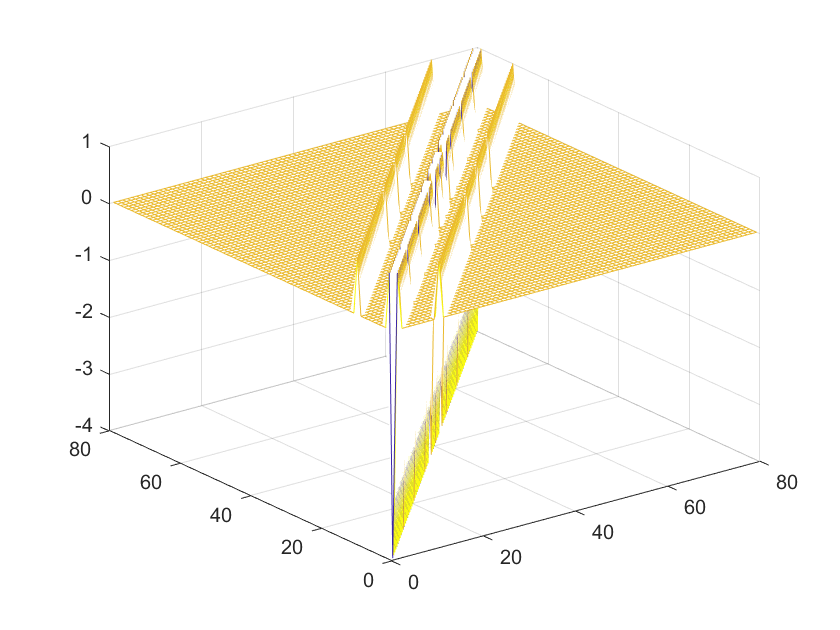

mesh(A)


C = zeros(80,1);
for i =1:80

 %colonne et ligne par rapport à i

 if (i<=10)
 colonne = i+1;
 ligne = 2;

 elseif(i==20||i==30||i==40||i==50||i==60||i==70||i==80)
 colonne=11;
 ligne = 1+(i-mod(i,10))/10;

 else
 colonne=1 + mod(i,10);
% 5
 ligne = 2+(i-mod(i,10))/10;
 end

 C(i)=-rhoAir*c/k;
 if(colonne==colFen1 && ligne==ligFen-1)
 C(i)=C(i)-piece(ligFen,colFen1);
 elseif(colonne==colFen2 && ligne==ligFen-1)
 C(i)=C(i)-piece(ligFen,colFen2);
 elseif(colonne==colFen3 && ligne==ligFen-1)
 C(i)=C(i)-piece(ligFen,colFen3);
 elseif(colonne==colFen4 && ligne==ligFen-1)
 C(i)=C(i)-piece(ligFen,colFen4);
 elseif(colonne==colRad && ligne==ligRad+1)
 C(i)=C(i)-piece(ligRad,colRad);
 %t800 début
 elseif((ligne==ligMa1 || ligne==ligMa2 ) &&( colonne==colMa1 || colonne==colMa2))
 C(i)=35;
 elseif( ((colonne==colMa2+1 || colonne==colMa1-1) && (ligne==ligMa1 || ligne==ligMa2)) || ((colonne==colMa2 || colonne==colMa1) && (ligne==ligMa1-1 || ligne==ligMa2+1)) )
 C(i)=C(i)-piece(ligMa1,colMa1);
 %t800 fin
 elseif(i==1||i==10||i==71||i==80)
 C(i)=C(i)-50;
 elseif(colonne==2||colonne==11||ligne==2||ligne==9)
 C(i)=C(i)-25;
 end
end


Uvec=inv(A)*C;
for i =1:80
 %colonne et ligne par rapport à i

 if (i<=10)
% 7
 colonne = i+1;
 ligne = 2;

 elseif(i==20||i==30||i==40||i==50||i==60||i==70||i==80)
 colonne=11;
 ligne = 1+(i-mod(i,10))/10;

 else
 colonne=1 + mod(i,10);
 ligne = 2+(i-mod(i,10))/10;
 end

 piece(ligne,colonne)=Uvec(i);

end
piece

piece =    25.0000   25.0000   40.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000
   25.0000   26.9117   30.8443   27.8922   27.1552   26.9945   26.8238   26.4978   26.1076   25.7241   25.3625   25.0000
   25.0000   26.7498   28.5209   28.5169   28.6817   28.9463   28.7502   28.0075   27.1558   26.3737   25.6735   25.0000
   25.0000   26.5143   27.9199   28.9202   30.0559   31.3064   31.1707   29.5738   28.0819   26.8888   25.9053   25.0000
   25.0000   26.3348   27.6717   29.1356   31.2629   35.0000   35.0000   30.9824   28.6567   27.1420   26.0062   25.0000
   25.0000   26.1006   27.2441   28.6351   30.8074   35.0000   35.0000   30.6465   28.3681   26.9636   25.9251   25.0000
   25.0000   25.7711   26.5164   27.3006   28.2793   29.5876   29.5650   28.1830   27.1529   26.3668   25.6779   25.0000
   25.0000   25.4149   25.6974   25.7192   25.3690   25.4537   25.4367   25.3152   25.6412   25.6204   25.3673   25.0000
   25.0000   25.1384   2

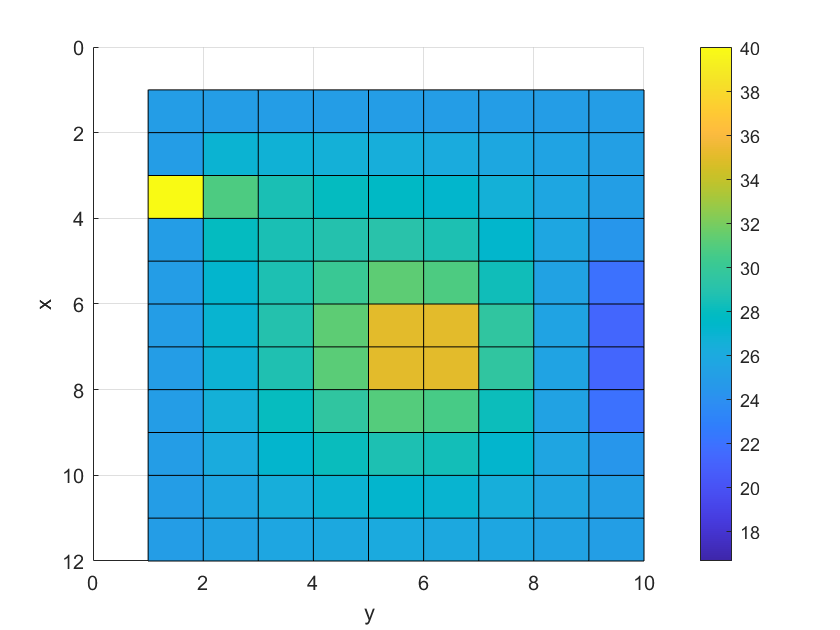

figure(1)
surf(piece)
xlabel('x');  ylabel('y')
view([90,90])
colorbar


% for ligne = m
%  for colonne = n
% 
%  scatter (colonne, ligne, 10, piece(ligne,colonne)) ; % de la couleur est la pression artérielle systolique
%  xlabel ( 'colonne' );
%  ylabel ( 'ligne' );
%  colorbar;
%  hold on;
% 
%  end
% end
% hold off;

[X,Y]=meshgrid(1:1:12,1:1:10); %longueur et largeur de la piece
[xq,yq] = meshgrid(0:.2:12, 0:.2:10); %précision d'interpolation
vq = griddata(X,Y,piece,xq,yq,'cubic')

vq =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    

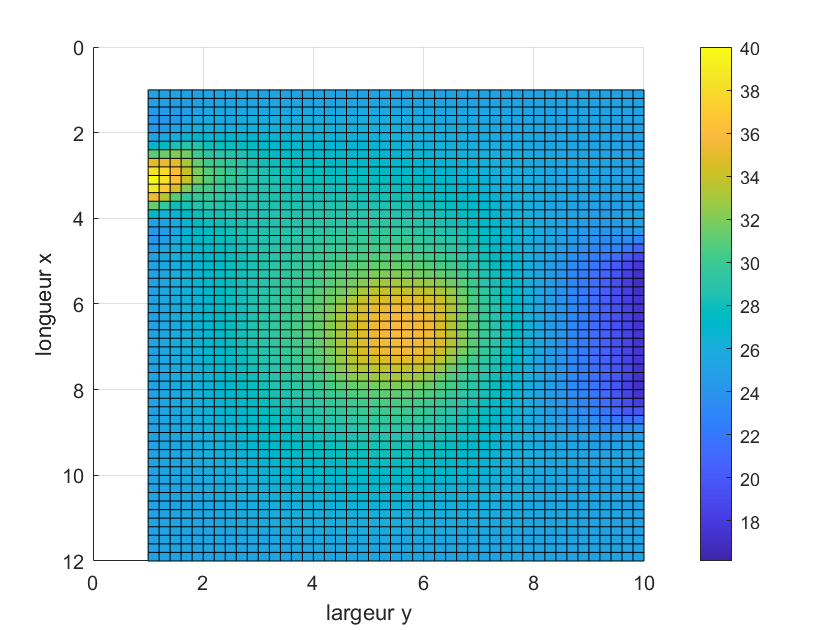

% figure(2)
% mesh(vq)
figure(3)
surf(xq,yq,vq)
xlabel('longueur x')
ylabel('largeur y')
zlabel('T °C')
% hold on
% plot3(X,Y,piece,'o')
view([90,90])
colorbar